clear 

% Construct the primal spatial grid
dom = [0,1];
Nx  = 101;

xPrimal = Grid1DUnifPrimal(dom,Nx);
xGrid   = GridSpace1D(xPrimal);

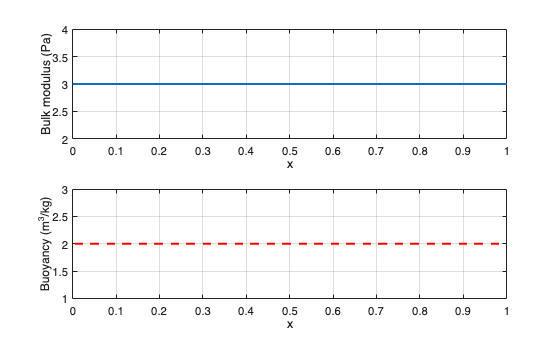

% Define a constant acoustic medium
medium = AcousticMedium1D.constant( ...
    BetaValue=2, ...
    KappaValue=3);

% Sample the medium onto the grids
[K,B,~,cMax] = sampleMedium1D( ...
    xGrid,medium, ...
    BetaGrid = "dual");

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on

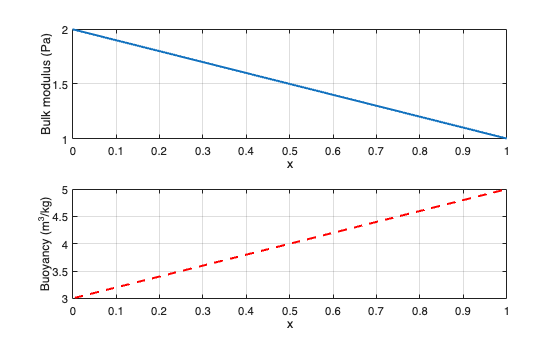

% Define a linear acoustic medium
medium = AcousticMedium1D.linear( ...
    KappaRange = [2,1], ...
    BetaRange  = [3,5], ...
    Domain     = dom);

% Sample the medium onto the grids
[K,B] = sampleMedium1D( ...
    xGrid,medium, ...
    BetaGrid = "dual");

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on

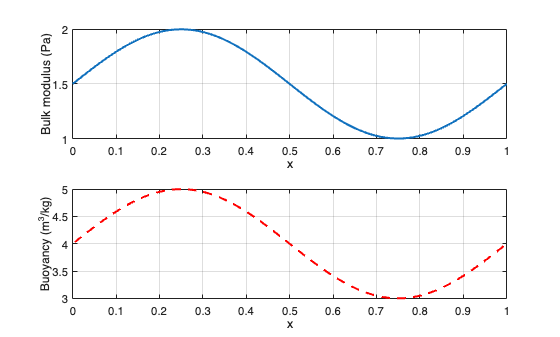

% Define a smooth acoustic medium
medium = AcousticMedium1D.smooth( ...
    KappaRange = [1,2], ...
    BetaRange  = [3,5], ...
    Domain     = dom);

% Sample the medium onto the grids
[K,B] = sampleMedium1D( ...
    xGrid,medium, ...
    BetaGrid = "dual");

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on

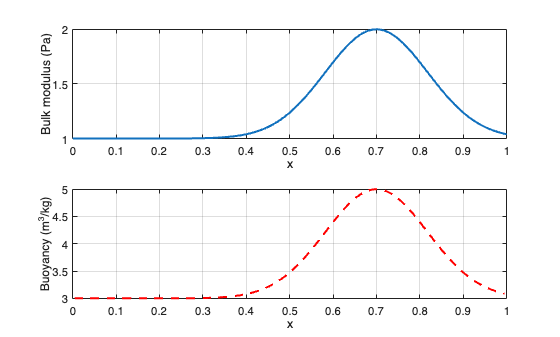

% Define a Gaussian peak acoustic medium
L = diff(dom);
xc = dom(1) + L*0.7;
medium = AcousticMedium1D.gaussianPeak( ...
    KappaRange = [1,2], ...
    BetaRange  = [3,5], ...
    Center     = xc, ...
    Width      = L/6 );

% Sample the medium onto the grids
[K,B] = sampleMedium1D( ...
    xGrid,medium, ...
    BetaGrid = "dual");

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on

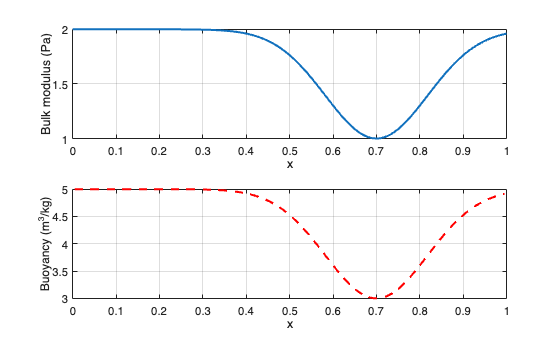

% Define a Gaussian peak acoustic medium
L = diff(dom);
xc = dom(1) + L*0.7;
medium = AcousticMedium1D.gaussianDip( ...
    KappaRange = [1,2], ...
    BetaRange  = [3,5], ...
    Center     = xc, ...
    Width      = L/6 );

% Sample the medium onto the grids
[K,B] = sampleMedium1D( ...
    xGrid,medium, ...
    BetaGrid = "dual");

% Plotting medium parameters
figure

subplot(2,1,1)
K.plot("LineWidth",1.5);
grid on

subplot(2,1,2);
B.plot("--r","LineWidth",1.5,"MarkerSize",3);
grid on